## 0. Data Generation

variances = [0, 0.005,0.01,0.025,0.05,0.1];

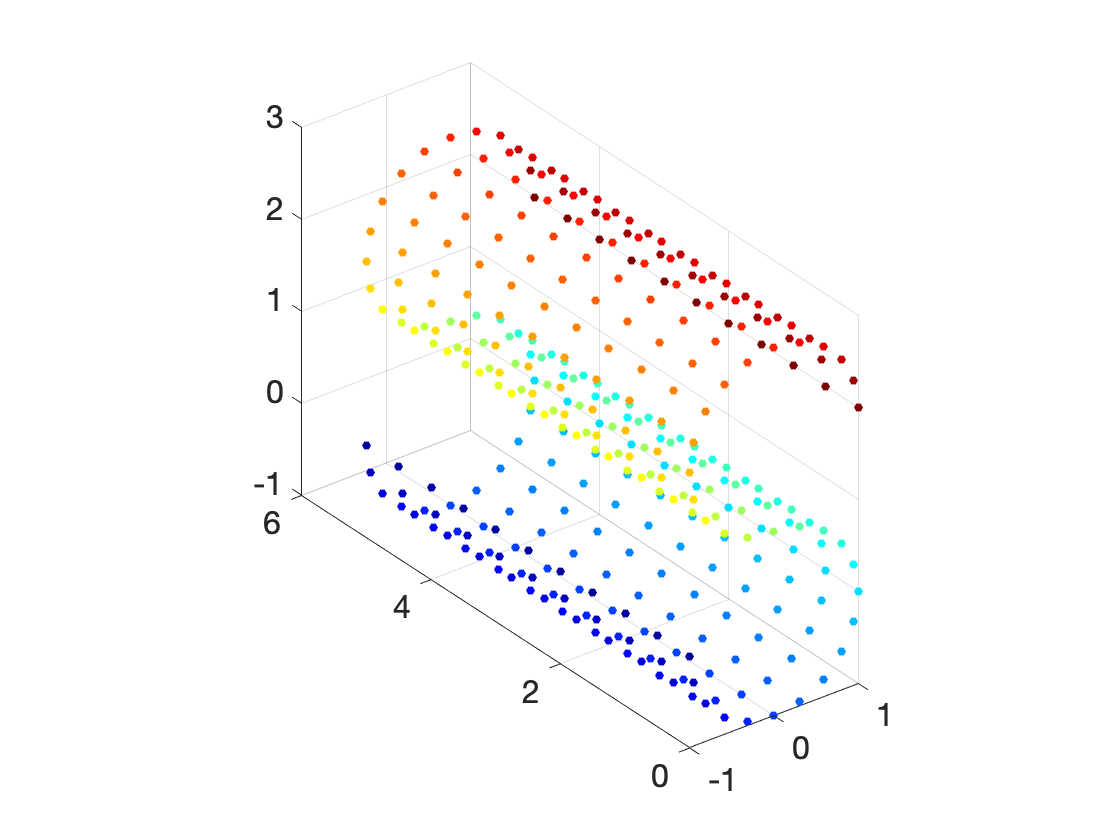

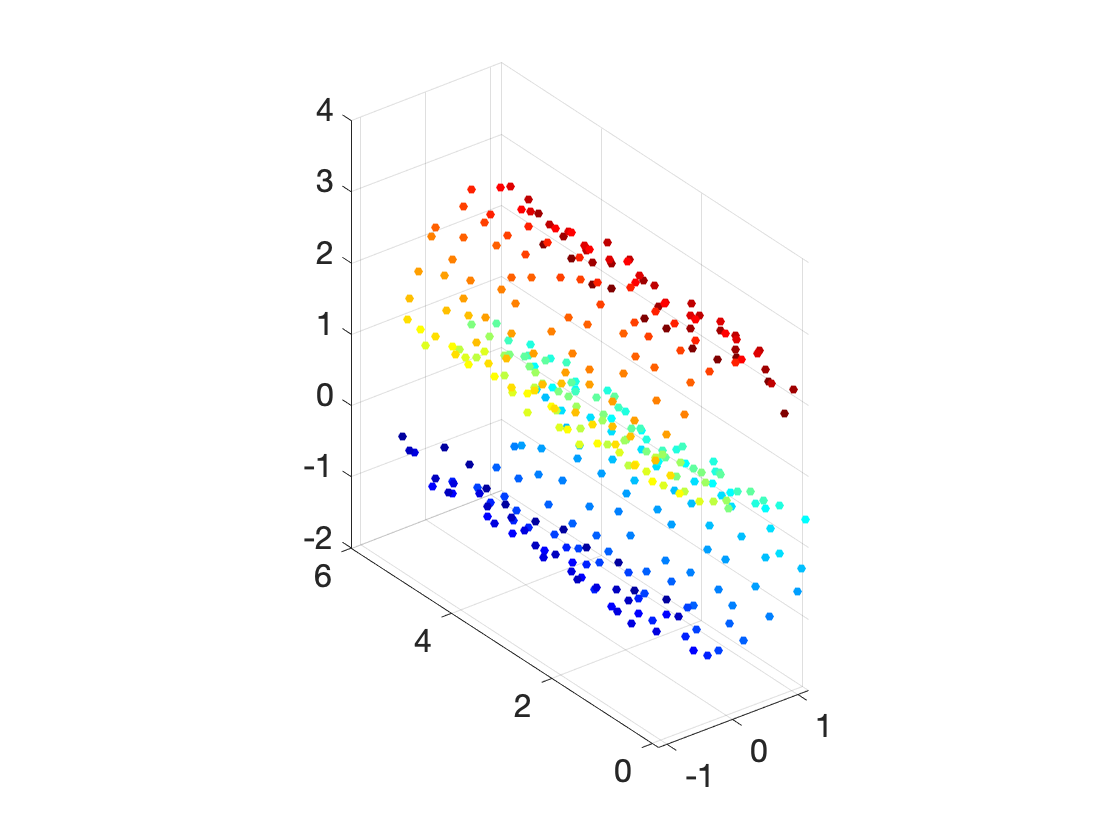

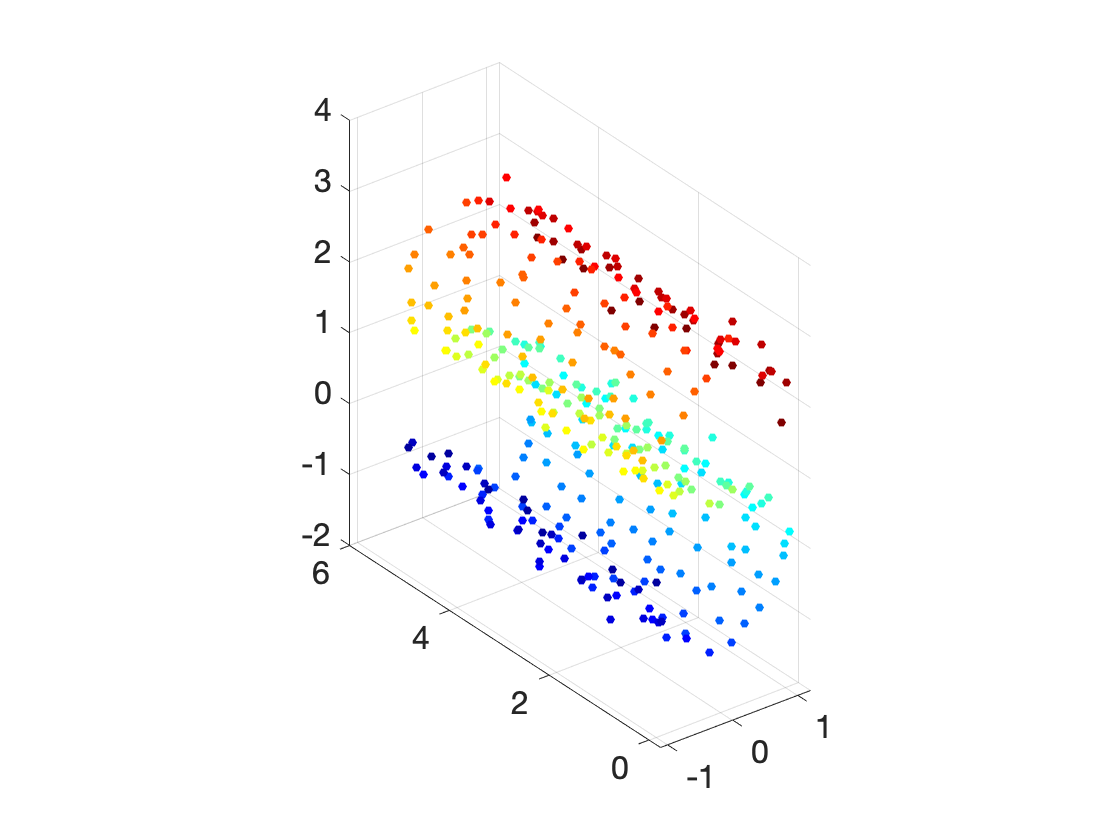

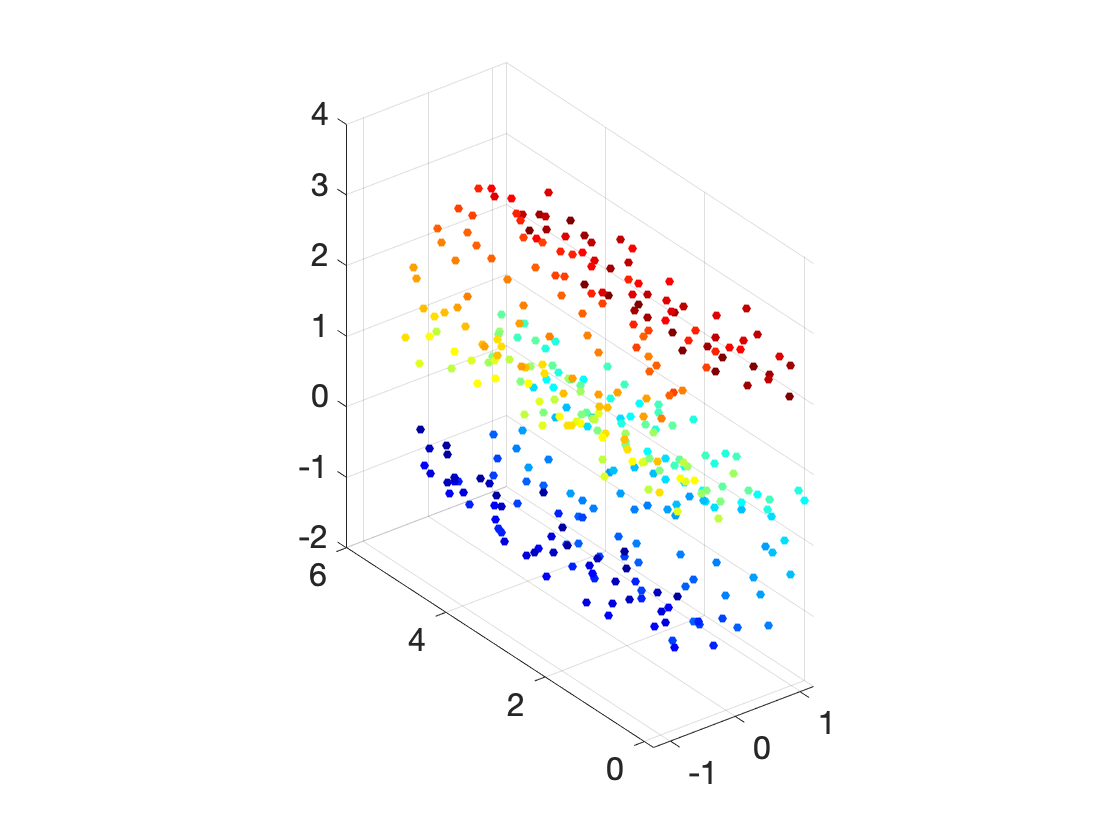

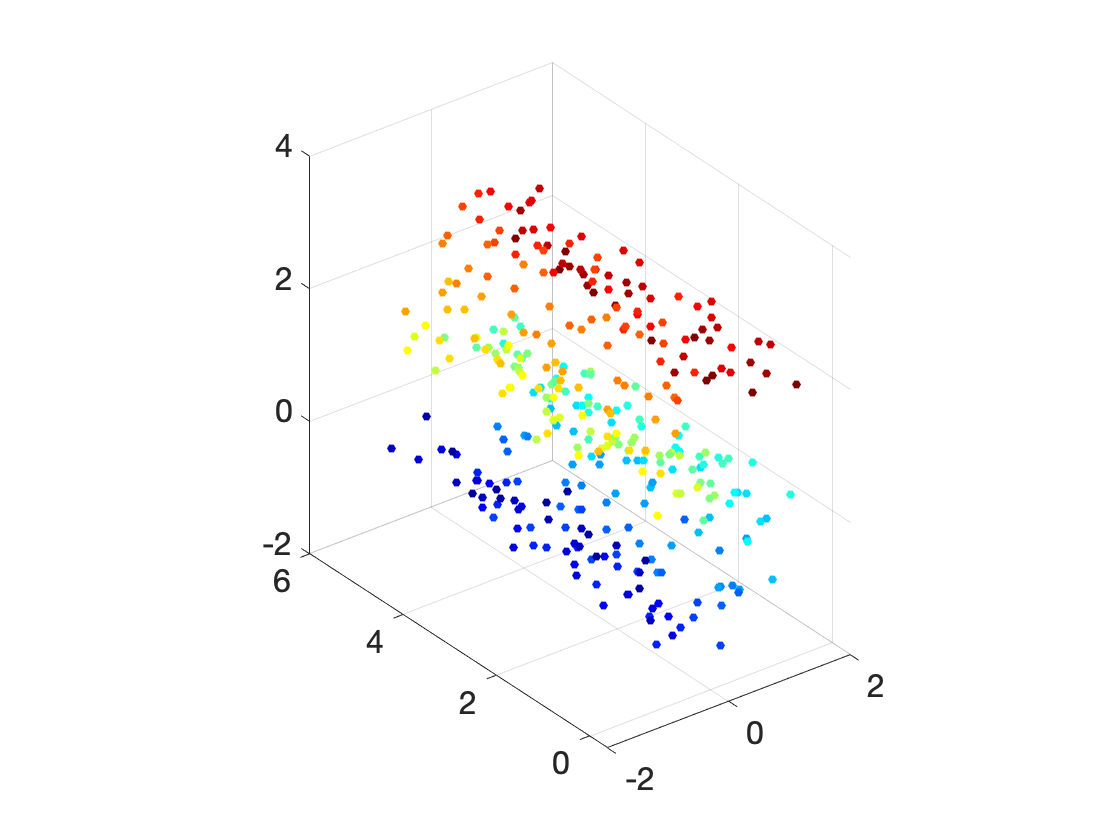

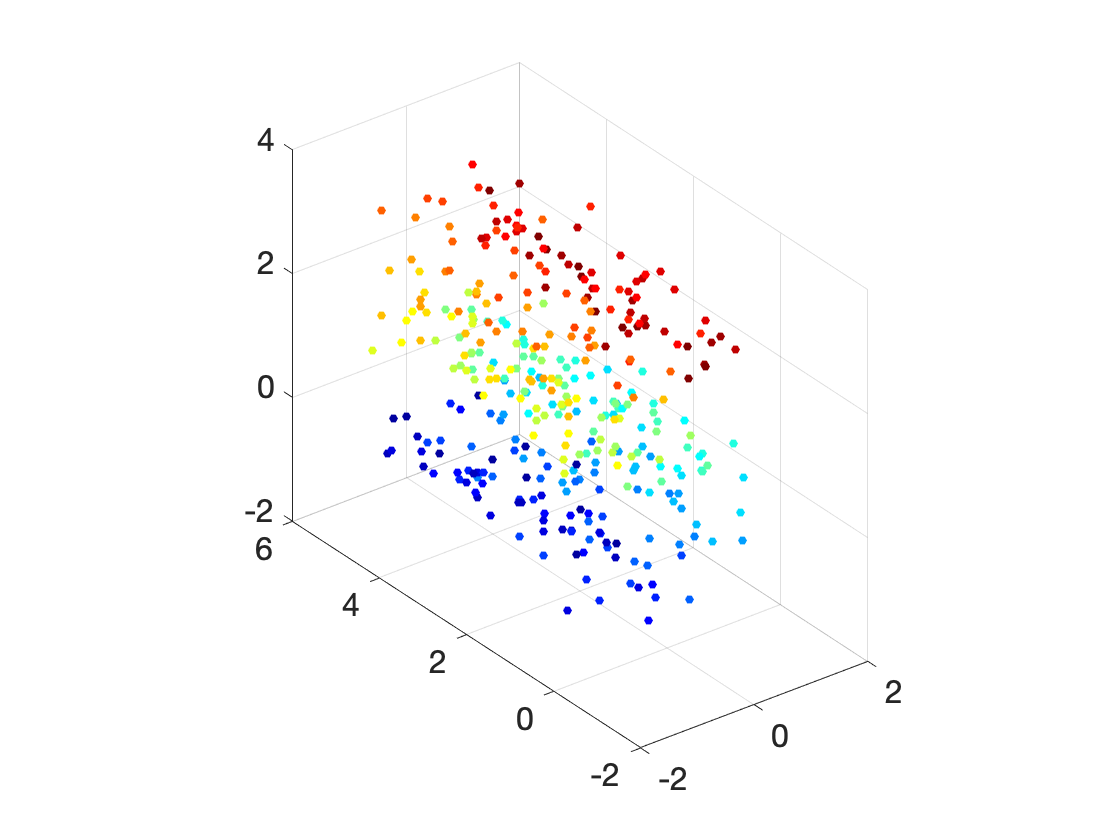

% generate data files
for variance = [0, 0.005,0.01,0.025,0.05,0.1]
    MakeScurveData(variance);
end

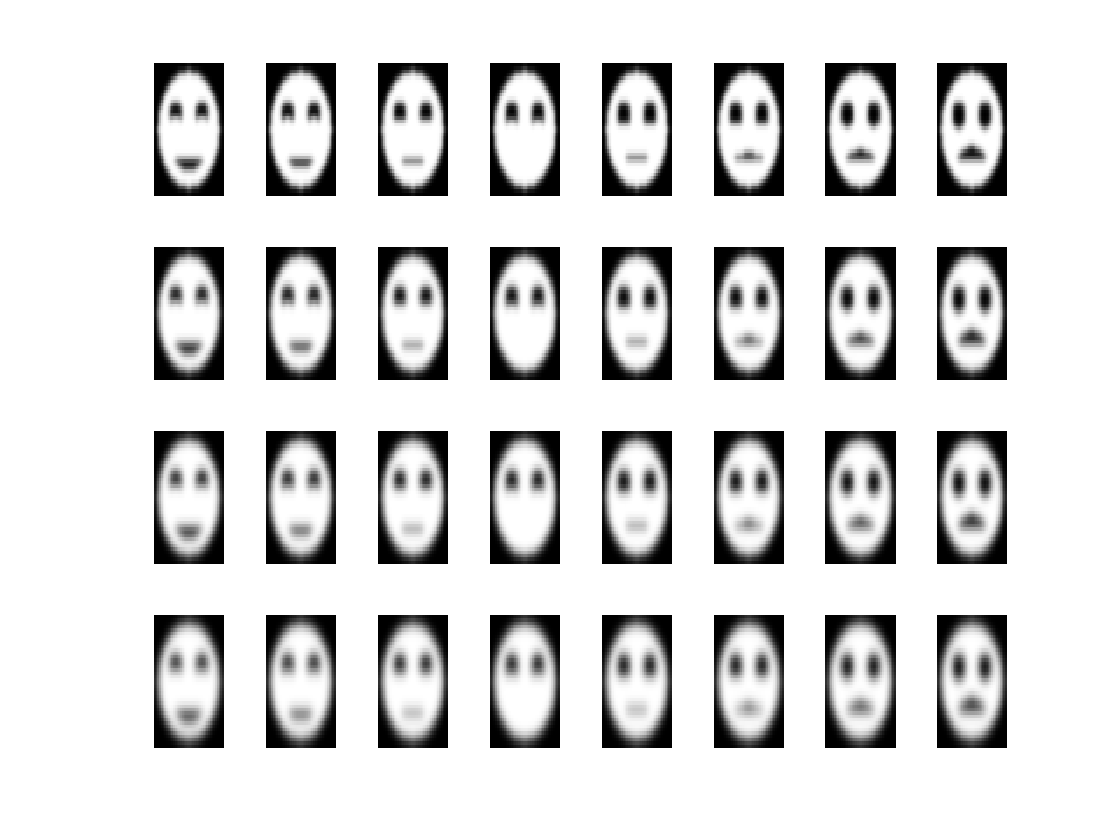

MakeEmojiData();

## 1. PCA

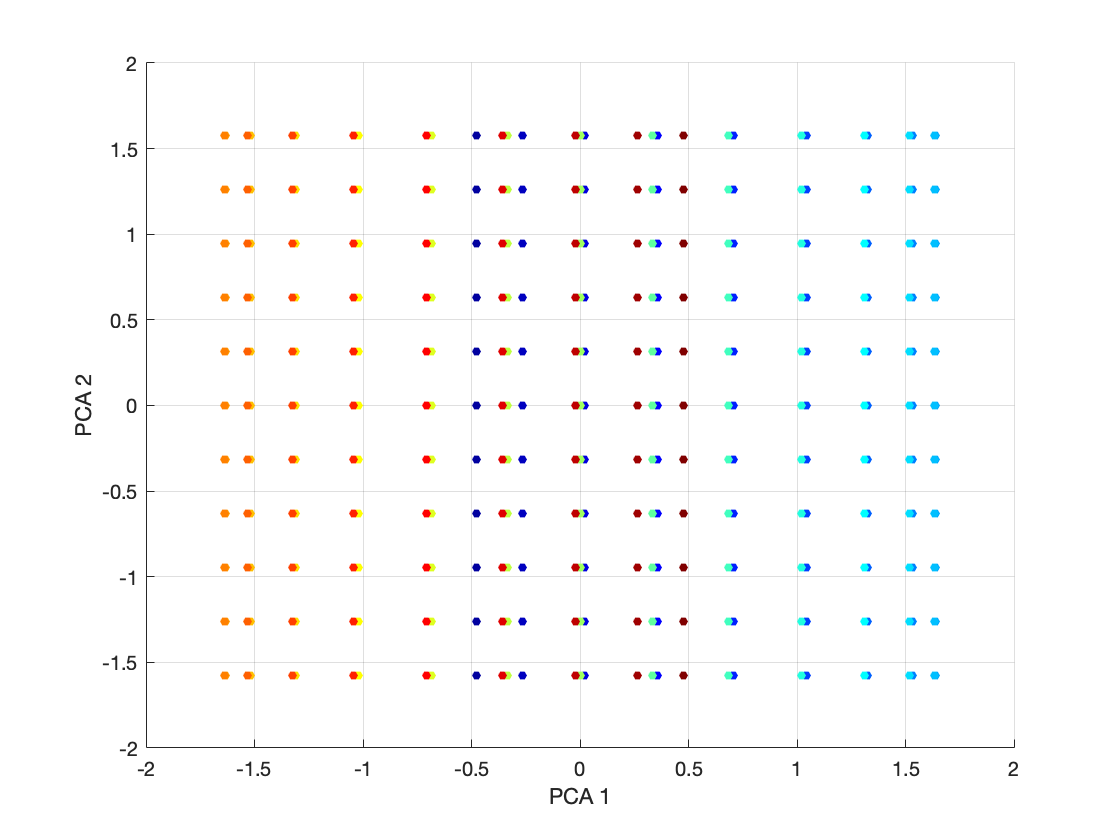

% perform pca on S-curve data
for variance = variances
    name = '';
    if variance > 0
        name = ['_' num2str(variance) '_'];
    end
    data = load(['data/ScurveData' name '.mat']);
    X = data.data3; c = data.color;
    PCA(X,['figures/pca2_ScurveData' name '.png'],2,c);
    PCA(X,['figures/pca3_ScurveData' name '.png'],3,c);
end

% perform pca on Emoji data
data = load('data/FaceData.mat');
X = data.data3; c = data.c_;
PCA(X,['figures/pca2_FaceData.png'],2,c);
PCA(X,['figures/pca3_FaceData.png'],3,c);

## 2. Isomap

% perform isomap on S-curve data
for variance = variances
    name = '';
    if variance > 0
        name = ['_' num2str(variance) '_'];
    end
    X = load(['data/ScurveData' name '.mat']).data3;
    Isomap(X,['ScurveData' name],10);
end
% perform isomap on Emoji data
X = load(['data/FaceData.mat']).data3;
Isomap(X,['FaceData'],25);

## 3. LLE

% perform lle on S-curve data
for variance = variances
    name = '';
    if variance > 0
        name = ['_' num2str(variance) '_'];
    end
    data = load(['data/ScurveData' name '.mat']);
    X = data.data3; c = data.color;
    % 2d
    Y = lle(X,10,2);
    figure;
    hold on; grid;
    scatter(Y(1,:),Y(2,:),20,c,'filled');
    %saveas(gcf,['figures/lle2_ScurveData' name '.png']);
    %3d
    Y = lle(X,10,3);
    figure;
    hold on; grid;
    scatter3(Y(1,:),Y(2,:),Y(3,:),20,c,'filled');
    view(3);
    %saveas(gcf,['figures/lle3_ScurveData' name '.png']);
end
% perform lle on Emoji data
data = load('data/FaceData.mat');
X = data.data3; c = data.c_;
%2d
Y = lle(X(3:end,:),10,2);
figure;
hold on; grid;
scatter(Y(1,:),Y(2,:),20,c(3:end,:),'filled');
saveas(gcf,['figures/lle2_FaceData.png']);

%3d
Y = lle(X,10,3);
figure;
hold on; grid;
scatter3(Y(1,:),Y(2,:),Y(3,:),20,c,'filled');
view(3);saveas(gcf,['figures/lle3_FaceData.png']);

## 4. t-SNE

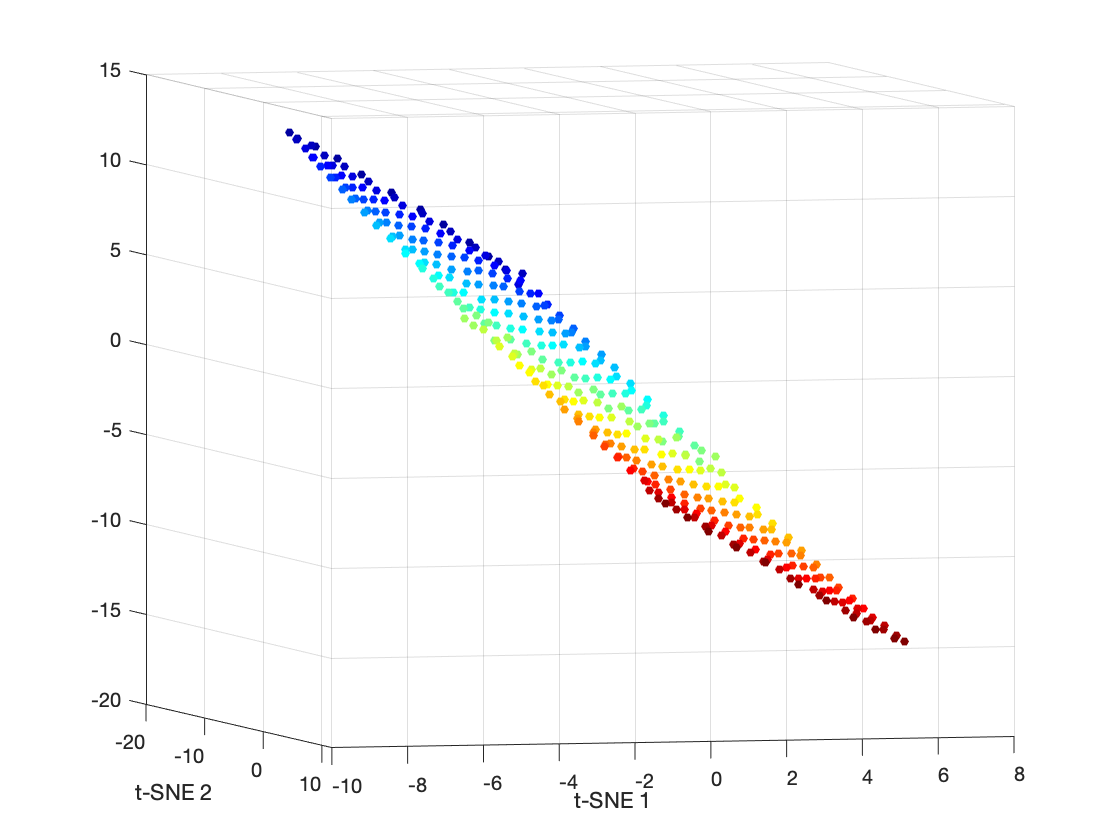

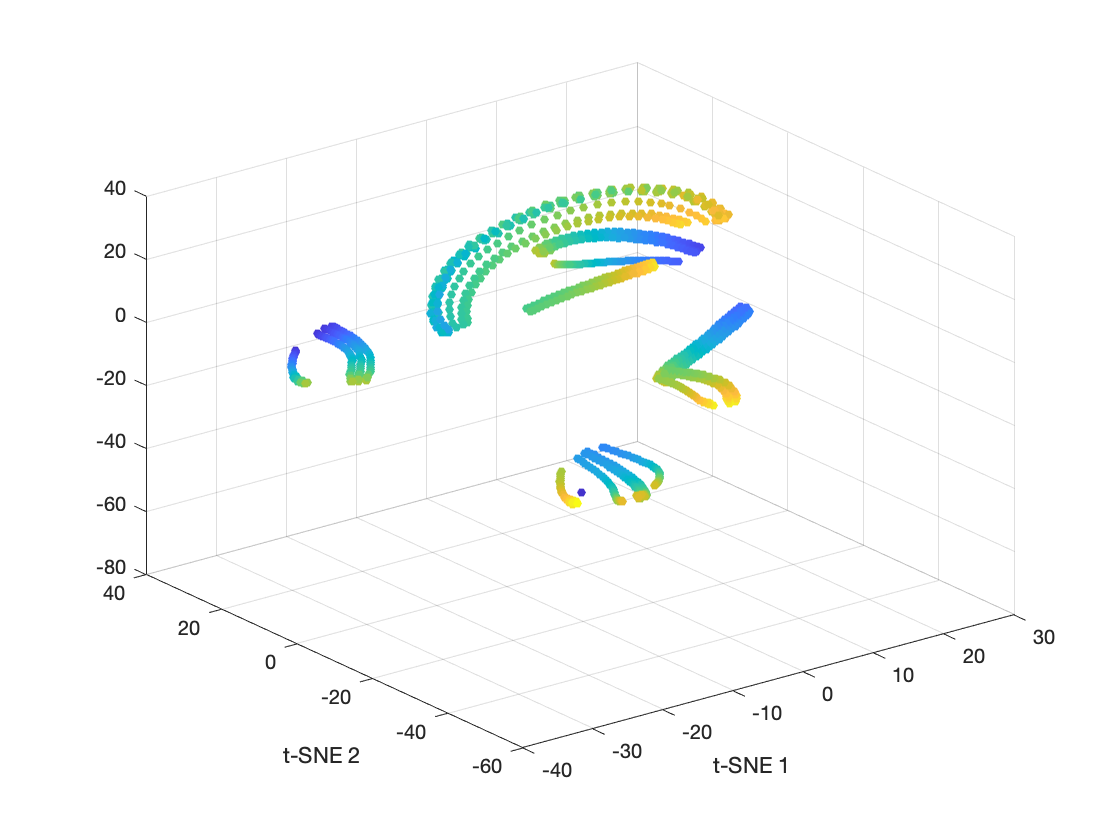

% perform tsne on S-curve data
for variance = variances
    name = '';
    if variance > 0
        name = ['_' num2str(variance) '_'];
    end
    data = load(['data/ScurveData' name '.mat']);
    X = data.data3; c = data.color;
    Y = tsne(X);
    figure;
    hold on; grid;
    scatter(Y(:,1),Y(:,2),20,c,'filled');
    xlabel('t-SNE 1');
    ylabel('t-SNE 2');
    saveas(gcf,['figures/tsne_ScurveData' name '.png']);
end
% perform tsne on Emoji data
X = load(['data/FaceData.mat']);
Y = tsne(X.data3);
figure;
hold on; grid;
scatter(Y(:,1),Y(:,2),10,X.c_,'filled');
xlabel('t-SNE 1');
ylabel('t-SNE 2');
saveas(gcf,'figures/tsne_EmojiData.png');

## 5. Diffusion Map

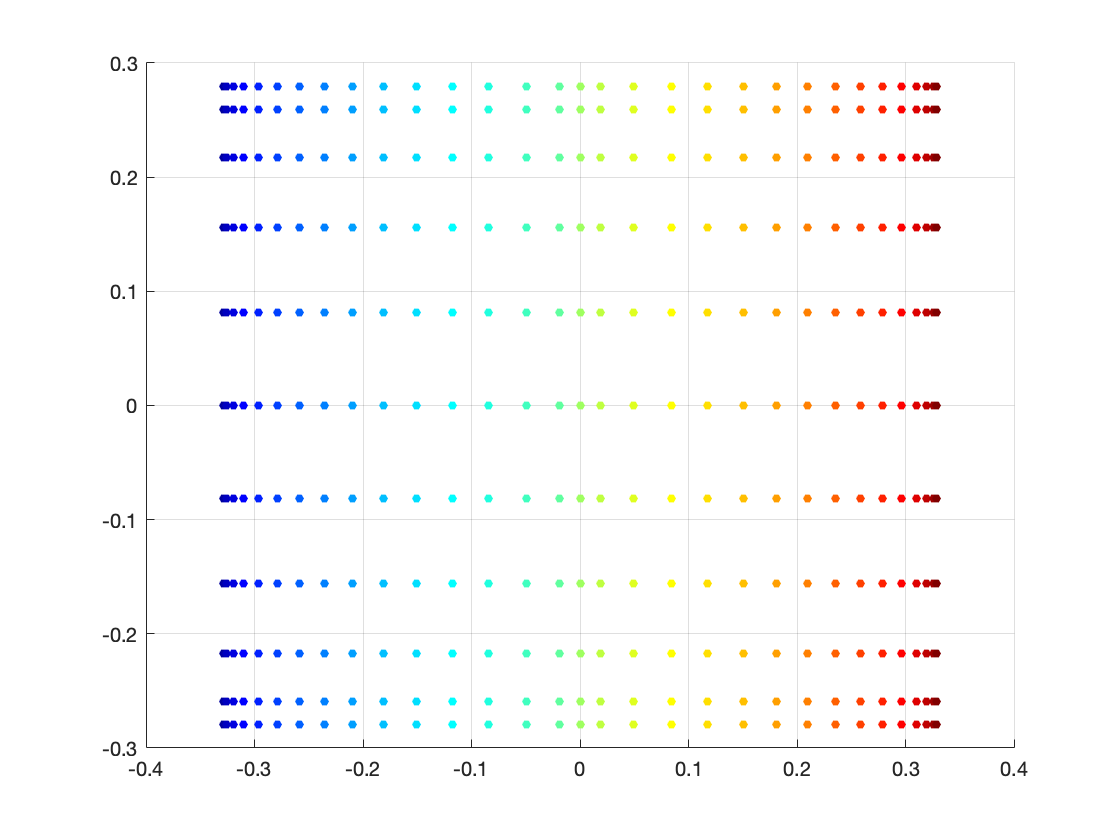

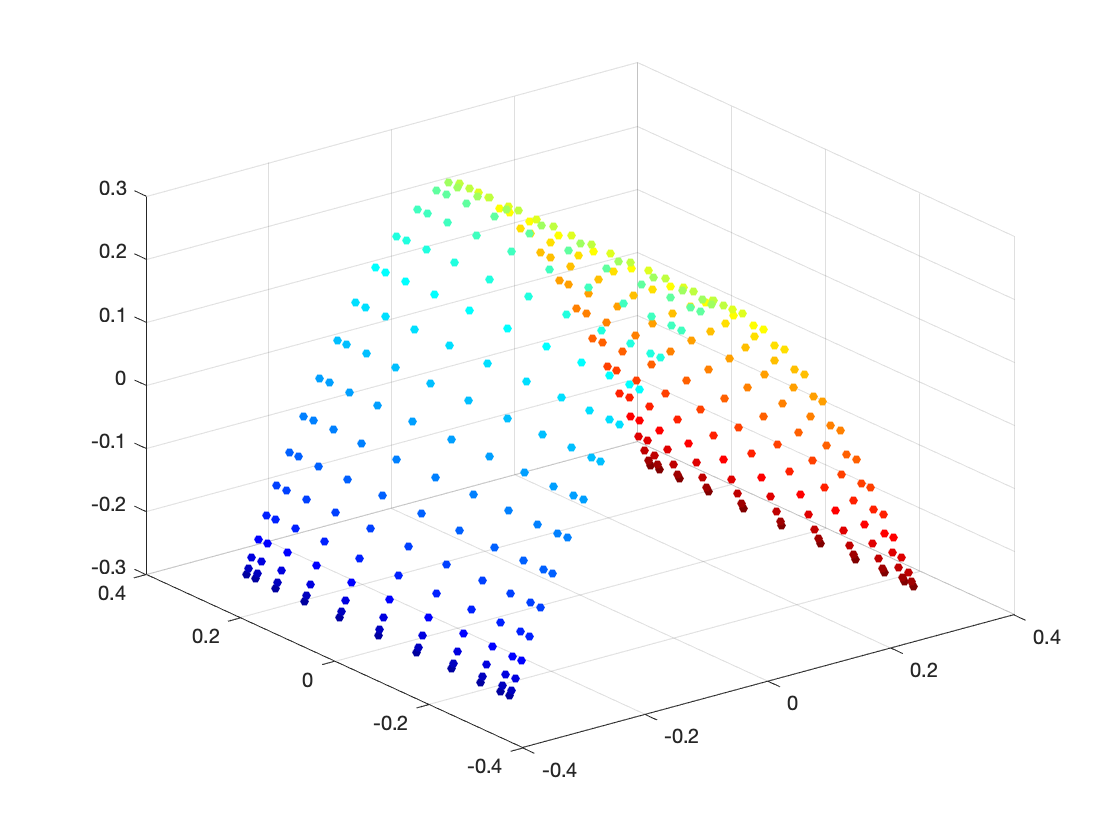

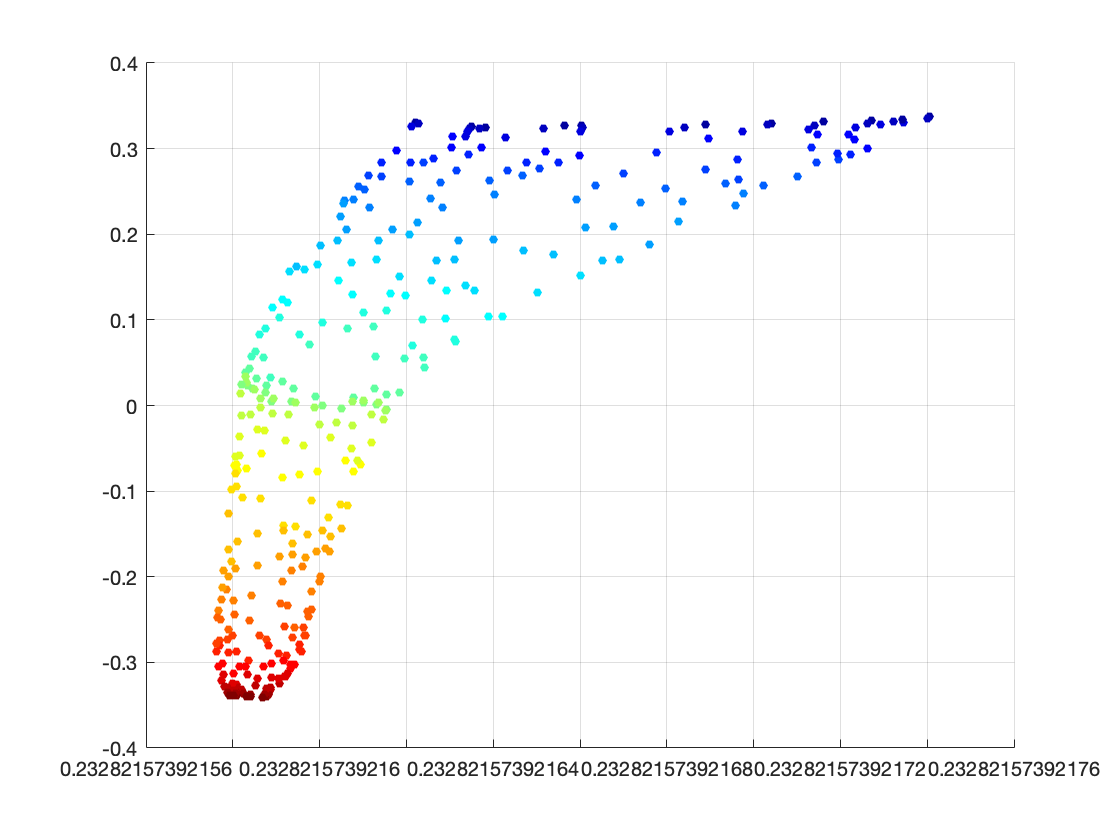

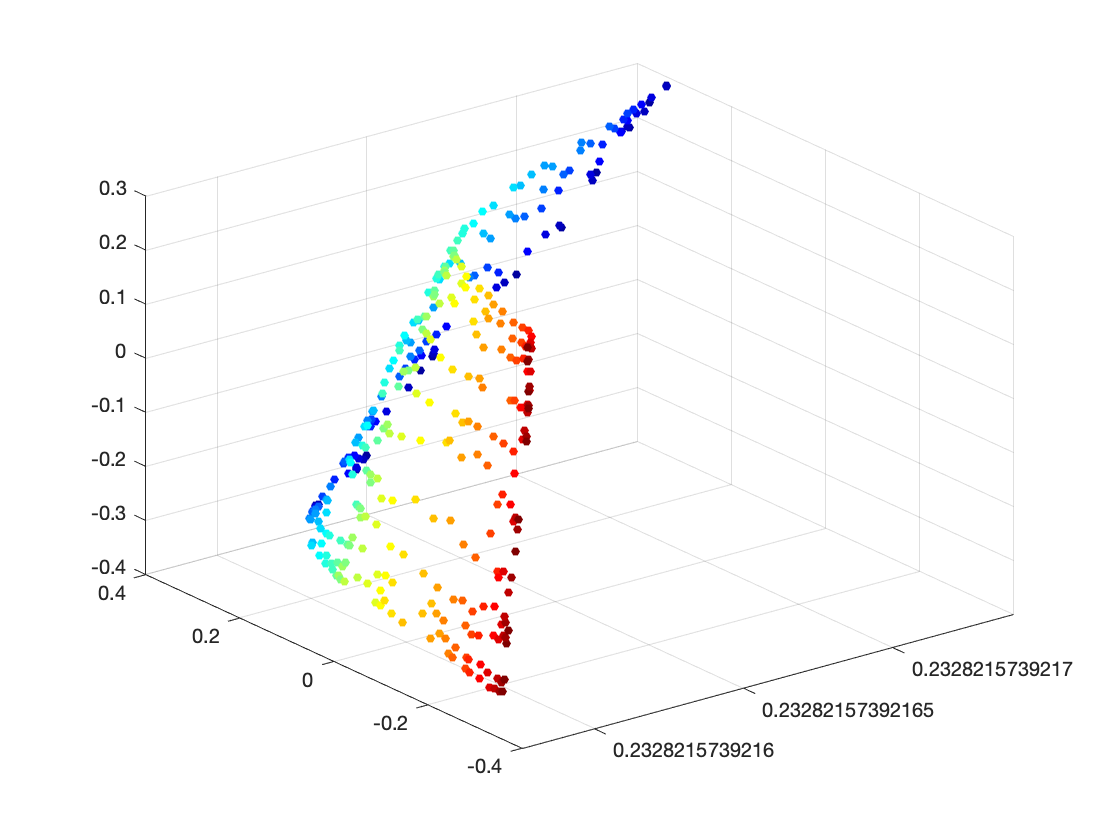

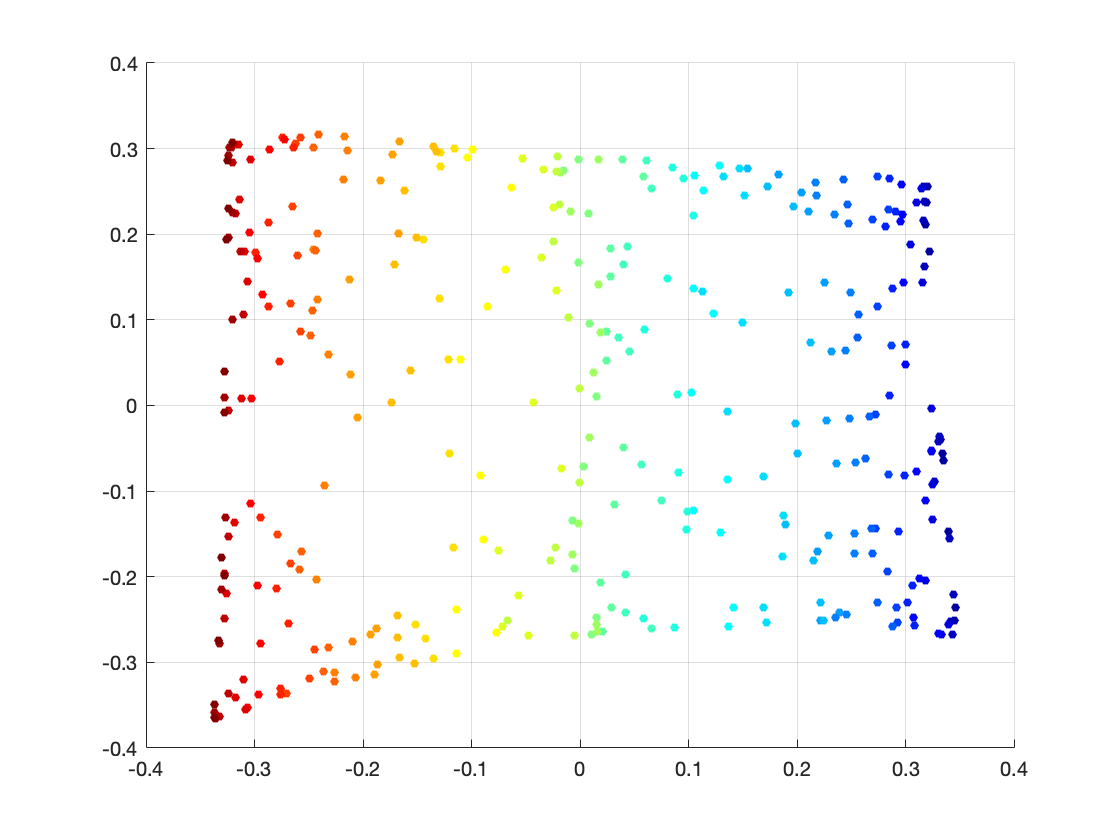

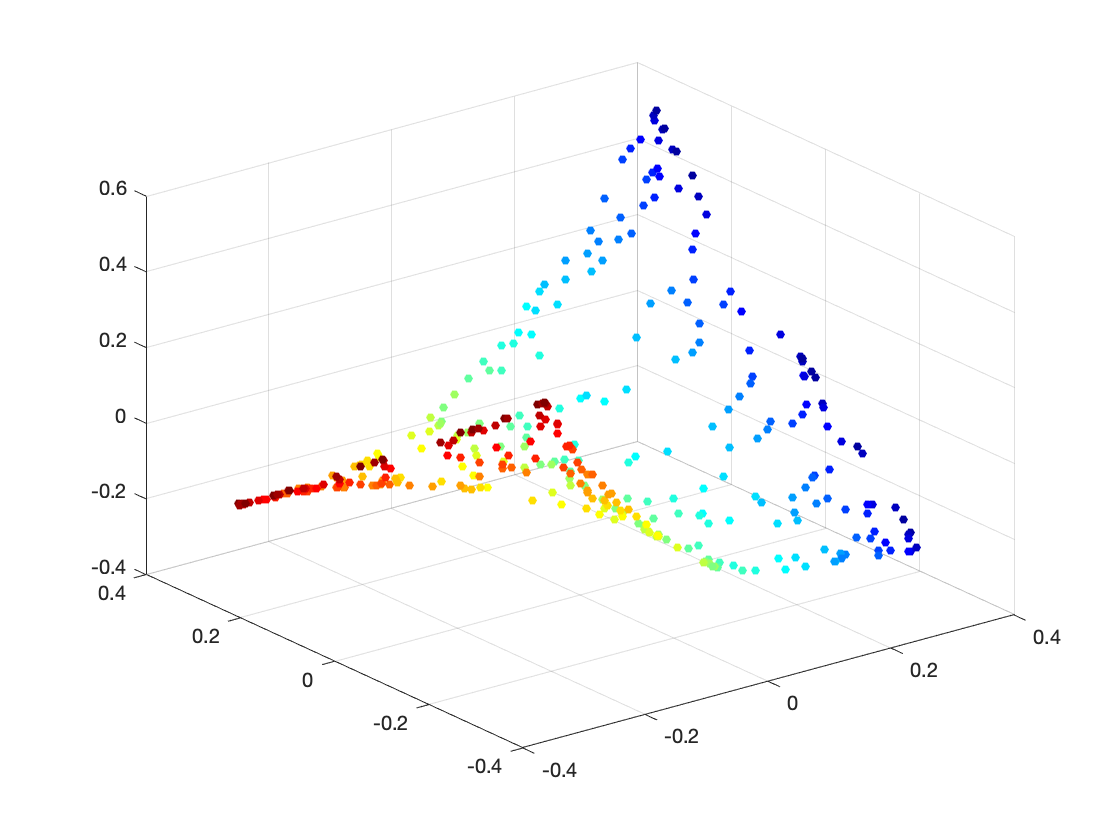

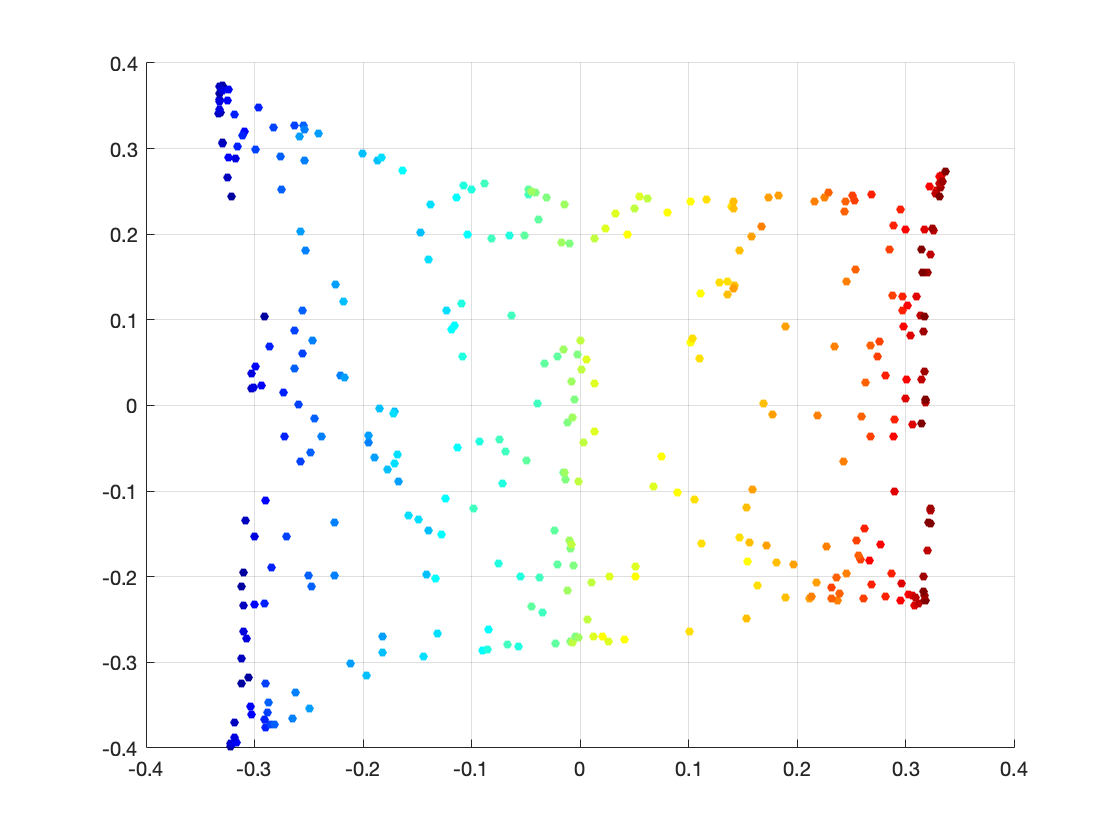

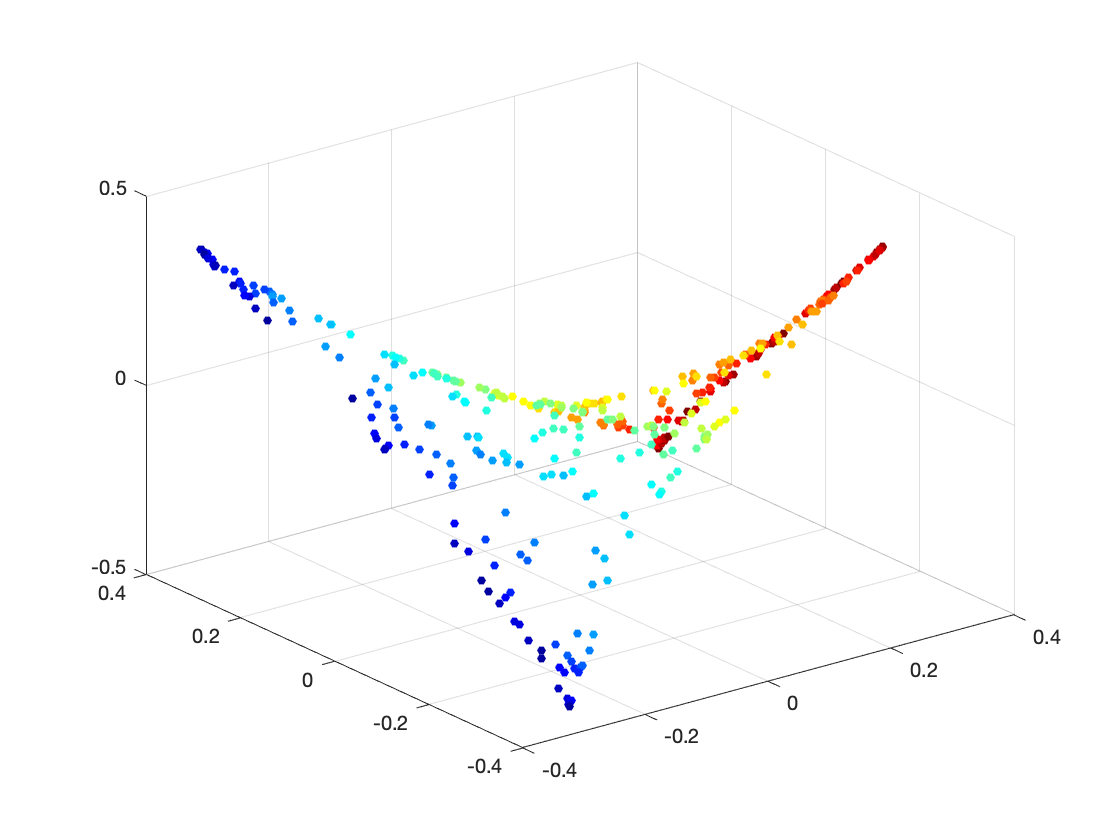

% perform diffusion map on S-curve data
for variance = variances
    name = '';
    if variance > 0
        name = ['_' num2str(variance) '_'];
    end
    data = load(['data/ScurveData' name '.mat']);
    X = data.data3; c = data.color;
    t = 10; % random walk steps
    % 2d
    DiffusionMap(X,t,c,['ScurveData' name '.png'],2);
    % 3d
    DiffusionMap(X,t,c,['ScurveData' name '.png'],3);
end

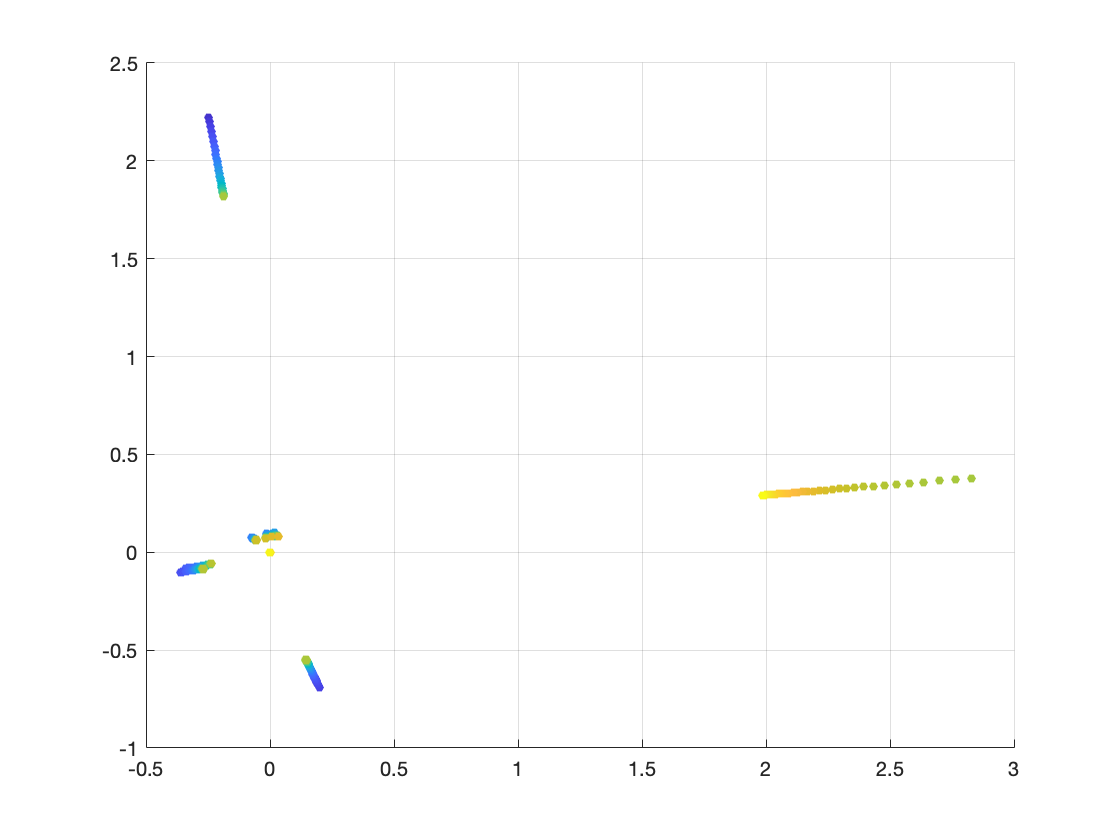

% perform lle on Emoji data
data = load('data/FaceData.mat');
X = data.data3(3:end,:); 
c = data.c_(3:end,:);
DiffusionMap(X,10,c,['FaceData.png'],2);

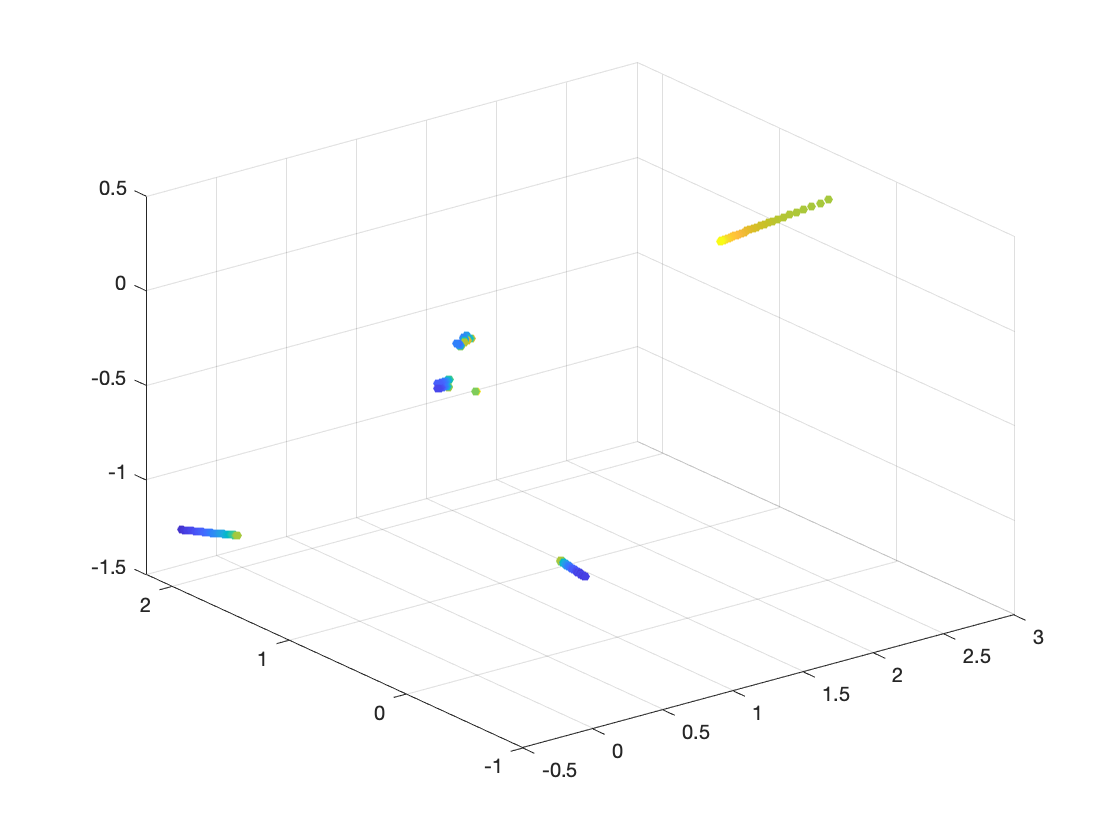

DiffusionMap(X,10,c,['FaceData.png'],3);